This is the exploratory analysis that inspired the **S**pectral **D**erivate **P**igment (SDP) algorithm, a.k.a. my preferred name, the **K**ramer et al. **R**eflectance **A**nomaly and **P**igment (KRAP) algorithm.

We'll be looking at observations of the "phytoplankton absorption coefficient" (aph; tells us how much light algae are absorbing) and concentrations of various phytoplankton pigments (provides information on the density of different algal species). Data come from a long time series in the Santa Barbara Channel generated by the "Plumes and Blooms" project. They've been wrangled and pre-processed to bring to science-quality so here we're focusing on developing analyses to inform prediction of pigment concentrations from aph. 

% clear workspace, close figs
clear; close all;

% load data
load('pnb_surf_HPLC_QCed_2005toDec2018.mat');
load('pnb_aph_QCed_1997toJun2018.mat');

% look at data:
head(aph)

ans = 8×304 table
     yyyymmdd     cruise    station     aph400      aph401      aph402      aph403      aph404      aph405      aph406      aph407      aph408      aph409      aph410      aph411      aph412      aph413      aph414      aph415      aph416      aph417      aph418      aph419      aph420      aph421      aph422      aph423      aph424      aph425      aph426      aph427      aph428      aph429      aph430

head(pigs)

ans = 8×32 table
     yyyymmdd     cruise    station    depth    TChla     TChlb     TChlc    ABCar     Butfuco    Hexfuco    Allo     Diadino    Diato      Fuco     Perid      Zea     MVChla    DVChla    Chlide    MVChlb    DVChlb    Chlc1c2    Chlc3     Lut       Neo     Viola     Phytin    Phide    Pras    Gyro    [DV_Chl_a] w/2011 LOQs    [Pras] w/2011 LOQs
    __________    ______    _______    <s

size(aph)

ans =         1363         304


size(pigs)

ans =    758    32


Here we'll extract specific pigments that give us information on algal species composition and probe correlations amongst these pigments to get a sense of how algal species co-occur in this data set:

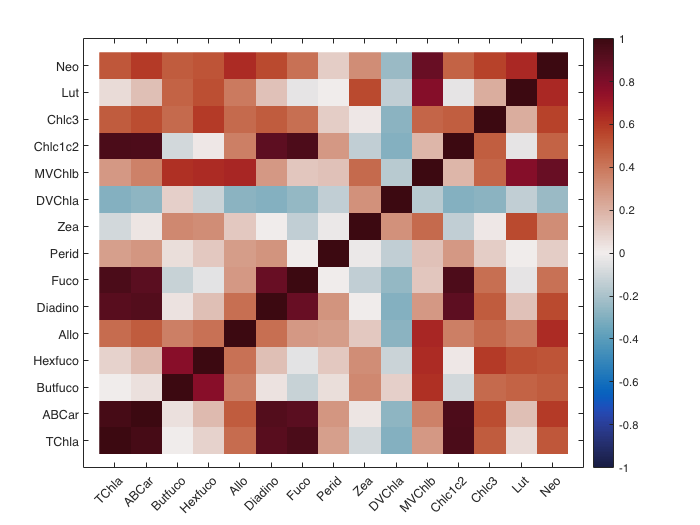

keep_pig = {'TChla', 'ABCar', 'Butfuco', 'Hexfuco',...
    'Allo', 'Diadino', 'Fuco', 'Perid', 'Zea', ...
    'DVChla', 'MVChlb', 'Chlc1c2', 'Chlc3', 'Lut', ...
    'Neo'};

pigmat = table2array(pigs(:, ...
    ismember(pigs.Properties.VariableNames,...
    keep_pig)));
% pigmat is matrix ready for math


% correlation matrix:
[r, p] = corr(pigmat, 'type', 'Pearson'); % pearson correlation

cmap = cmocean('balance'); % colormap
% plot correlation matrix:
figure(); hold on; box on;
imagesc(r);
c = colorbar; colormap(cmap); caxis([-1 1]);
ax = gca; 
ax.XTick = 1:size(pigmat,2); ax.YTick = 1:size(pigmat,2);
ax.XTickLabels = keep_pig; ax.YTickLabels = keep_pig;
ax.XTickLabelRotation = 45;

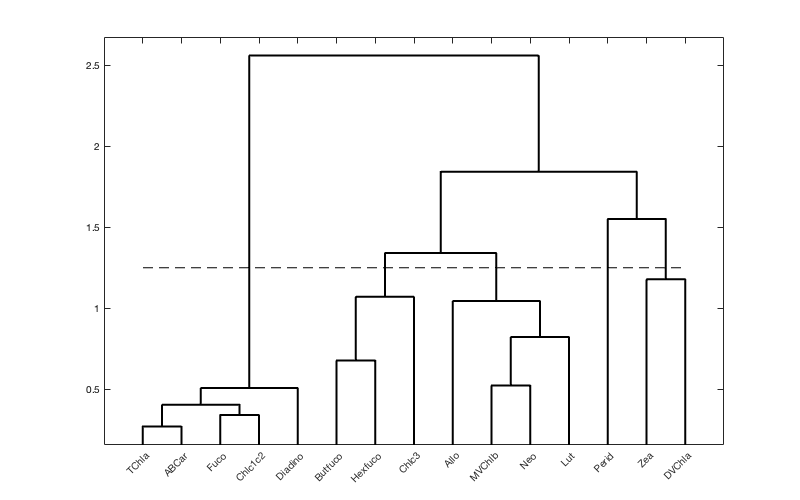


% cluster with correlation distance and wards linkage:
dd = pdist(pigmat', 'correlation');
% transform correlation distance for use with ward (prefers euclidean):
dd = sqrt( 2 .* dd );
ll = linkage(dd, 'ward');

[tree_plot] = dendrogram(ll,'Labels',keep_pig);
hold on; box on; 
ax = gca;
ax.XTickLabelRotation = 45;
set(tree_plot,'linewidth',2, 'Color','k');
% draw line to illustrate relevant clusters:
plot(1:length(keep_pig), 1.25 .* ones(length(keep_pig),1), 'k--')

% grab clusters for later:
pig_clusters = cluster(ll, 'Cutoff', 1.25, 'Criterion', 'distance');

These results make sense in the context of our study domain and what we know about algae. We see lots of positive correlation which makes sense - most algae tend to respond similarly to seasonal changes in growth conditions. The five clusters shown with a cutoff at 1.25 can be interpreted as five distinct algal taxa based on known pigment content of different algal taxa. If you're well-versed on algal pigments, you might pick out five widely used algal "biomarkers" to represent each cluster - Fuco, Hexfuco, MVChlb, Perid, and Zea. 

Let's see how each of these clusters relates to algal absorption. We'll align the data sets, correlate pigments and aph, and look at "correlation spectra" for each cluster of pigments:

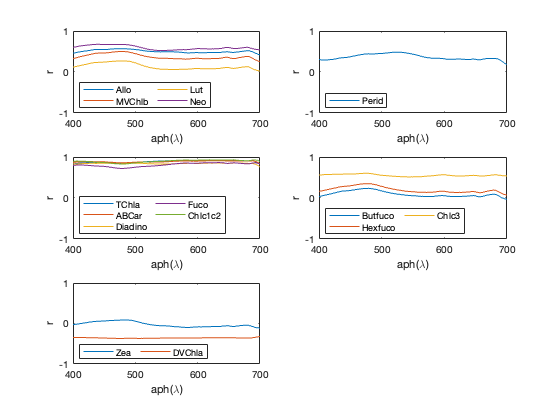

% join tables to align the two data sets:
pig_aph_match = innerjoin(pigs, aph, "Keys", ["yyyymmdd", "cruise", "station"]);

% extract matrices:
pigmat = table2array(pig_aph_match(:, keep_pig));
aphmat = table2array(pig_aph_match(:, contains(pig_aph_match.Properties.VariableNames, 'aph')));
% parse variable names to keep aph wl:
wl = pig_aph_match.Properties.VariableNames(contains(pig_aph_match.Properties.VariableNames, 'aph'));
wl = str2double(strrep(wl, 'aph', '')); % numeric vector 

% correlate:
[r, p] = corr([pigmat, aphmat], 'type', 'Pearson', 'rows', 'complete'); % rows, complete handles missing data
% parse correlation matrix to pig x aph:
r_pigXaph = r(1:size(pigmat,2), size(pigmat,2)+1:end);
p_pigXaph = r(1:size(pigmat,2), size(pigmat,2)+1:end);

% plot correlation spectra by pigment cluster:
uclust = unique(pig_clusters);
figrow = ceil(sqrt(max(uclust))); 
figcol = floor(sqrt(max(uclust)));
figure(); hold on;
for i = 1:length(uclust)

    % pigments from cluster i's correlation spectra:
    rspeci = r_pigXaph(pig_clusters == uclust(i), :);
    pspeci = p_pigXaph(pig_clusters == uclust(i), :);
    pig_legend = keep_pig(pig_clusters == uclust(i));

    subplot(figrow, figcol, i); hold on; box on;

    plot(wl, rspeci);
    xlabel('aph(\lambda)'); ylabel('r');
    l = legend(pig_legend); l.Location = 'southwest'; l.NumColumns = 2;
    ax = gca; ax.YLim = [-1 1];
end

The relationships are not particularly strong for many pigments, except for the middle-left panel. These pigments are strongly correlated with the cumulative density of algae, which may explain their strong relationship with cumulative absorption. 

One way remote sensing scientists isolate signals from optical data is through "spectral derivative analysis". This involves applying a smoothing filter to remove high frequency measurement noise (which derivative analyses are sensitive to), and computing the derivatives of each spectra. Since our ultimate goal is to find strong relationships between pigments and absorption, we'll choose the type and width of our smoothing filter based on those that provide the strongest relationships between (suites of) pigments and their respective absorption maxima. 

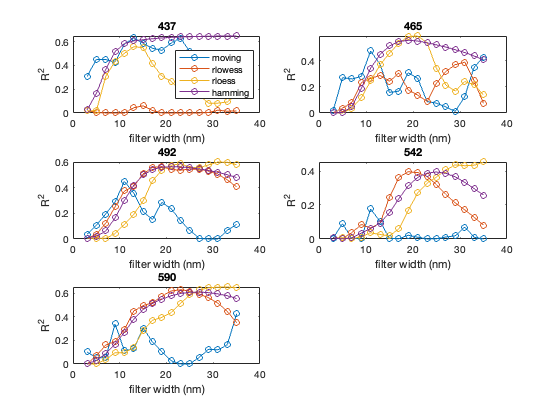

% test filter widths from 3-31 nm and 4 types:
filt_w = 3:2:35;
filt_type = {'moving', 'rlowess', 'rloess', 'hamming'};
% we're testing across these 5 absorption maxima derived from literature:
absmax = [437, 465, 492, 542, 590];

% initialize 3-d array for tracking stats:
% dim 1 = 5 = # of pigment absorption maxima comparisons (from literature)
% dim 2 = filter types, dim3 = widths 
all_R2 = nan(length(filt_w), length(absmax), length(filt_type));
for i = 1:length(filt_type)
    smooth_spec = smooth_spectra(aphmat, filt_type{i}, filt_w);
    R2 = cellfun(@(x) lm_pig_vs_absmax(pigmat, keep_pig, x, wl), smooth_spec, ...
        'UniformOutput', false);
    all_R2(:, :, i) = cell2mat(R2);
end

% plot to look for best filter type/width combo:
figrow = ceil(sqrt(length(absmax))); 
figcol = floor(sqrt(length(absmax)));
figure(); hold on;
for i = 1:length(absmax)

    subplot(figrow, figcol, i); hold on; box on;
    title(num2str(absmax(i)));
    plot(filt_w, squeeze(all_R2(:, i, :)), '-o');
    xlabel('filter width (nm)'); ylabel('R^2');
    if i == 1
        l = legend(filt_type); l.Location = 'east';
    end

end

Hamming is consistently at the top of the pile. Look at that more closely:

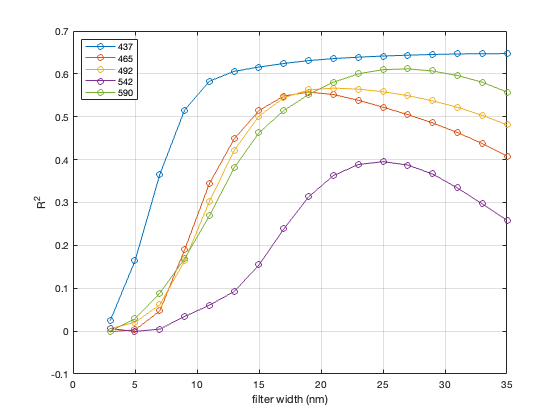

ham_results = squeeze(all_R2(:, :, ismember(filt_type, 'hamming')));
figure(); hold on; box on; grid on;
plot(filt_w, ham_results, '-o');
xlabel('filter width (nm)'); ylabel('R^2');
l = legend(cellstr(num2str(absmax'))); l.Location = 'northwest';

There's no best answer that's perfect for all the absorption features we're interested in. A 19 nm Hamming window filter seems to be a good compromise, so let's use that. Here we'll apply the filter, compute derivatives, and correlate with pigments. 

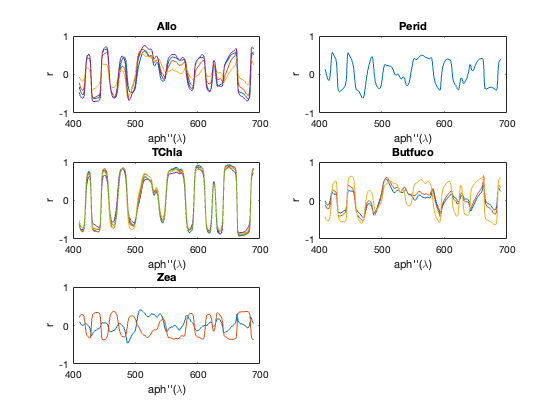

filt_w = 19;
filt_type = 'hamming';
smooth_spec = smooth_spectra(aphmat, filt_type, filt_w);
[d1, d2, dwl] = calc_spec_derivative(smooth_spec, wl); % just get 2nd derivative

% correlate:
[r, p] = corr([pigmat, d2], 'type', 'Pearson', 'rows', 'complete'); % rows, complete handles missing data
% parse correlation matrix to pig x aph:
r_pigXd2 = r(1:size(pigmat,2), size(pigmat,2)+1:end);
p_pigXd2 = r(1:size(pigmat,2), size(pigmat,2)+1:end);

% plot correlation spectra by pigment cluster:
figrow = ceil(sqrt(max(uclust))); 
figcol = floor(sqrt(max(uclust)));
figure(); hold on;
for i = 1:length(uclust)

    % pigments from cluster i's correlation spectra:
    rspeci = r_pigXd2(pig_clusters == uclust(i), :);
    pspeci = p_pigXd2(pig_clusters == uclust(i), :);
    pig_legend = keep_pig(pig_clusters == uclust(i));

    subplot(figrow, figcol, i); hold on; box on;
    plot(dwl, rspeci);
    xlabel('aph''''(\lambda)'); ylabel('r');
%     l = legend(pig_legend); l.Location = 'south';
    title(pig_legend{1}); % pick 1 pigment for each cluster of correlation spectra
    % legend covers figures otherwise
    ax = gca; ax.YLim = [-1 1];
end

Nice. Visually it looks like we have stronger correlation with derivative spectra and correlation spectra are more coherent with pigment clusters compared to those found for the raw spectra (though still not perfect). Let's cluster to confirm:

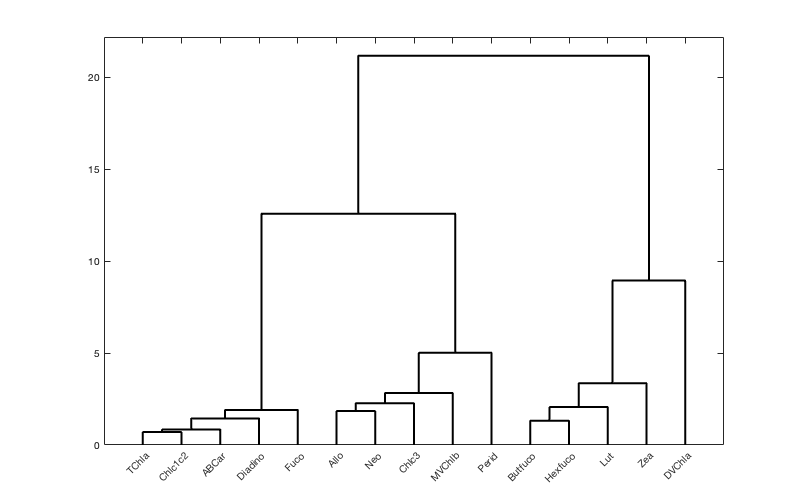

% cluster with euclidean (we're already in correlation space) distance and wards linkage:
dd = pdist(r_pigXd2, 'euclidean');
ll = linkage(dd, 'ward');

[tree_plot_d2] = dendrogram(ll,'Labels',keep_pig);
hold on; box on; 
ax = gca;
ax.XTickLabelRotation = 45;
set(tree_plot_d2,'linewidth',2, 'Color','k');

Compare with clustering of the correlation spectra with aph:

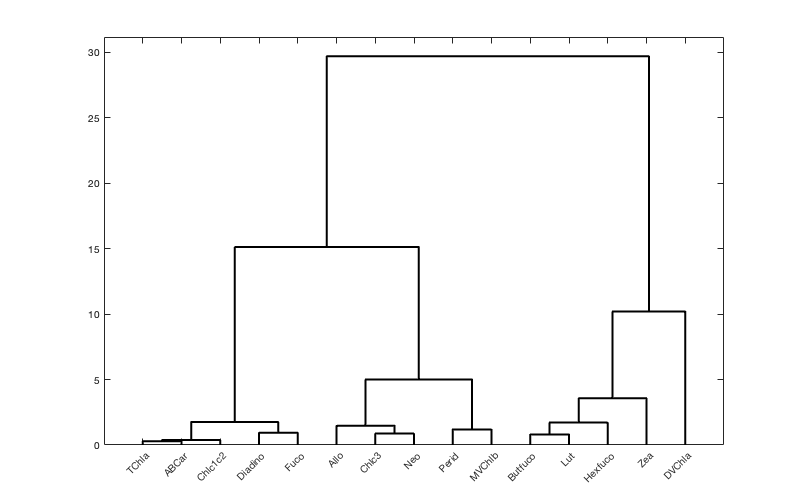

% cluster with euclidean (we're already in correlation space) distance and wards linkage:
dd = pdist(r_pigXaph, 'euclidean');
ll = linkage(dd, 'ward');

[tree_plot_aph] = dendrogram(ll,'Labels',keep_pig);
hold on; box on; 
ax = gca;
ax.XTickLabelRotation = 45;
set(tree_plot_aph,'linewidth',2, 'Color','k');

While neither aph correlation spectra nor the correlation spectra of it's 2nd derivative cluster identically to the pigments, the 2nd derivative correlation spectra offer more similar clusters to the pigments and in general have more distinct correlation spectra. So it seems those should be our predictors in our predictive modeling. Let's save the results for more streamlined predictive analysis:

pigs = pig_aph_match(:, keep_pig); % just store these
save('pnb_pigs_aph_2nd_deriv.mat', 'd2', 'dwl', 'pigs')